# Graficos 3D

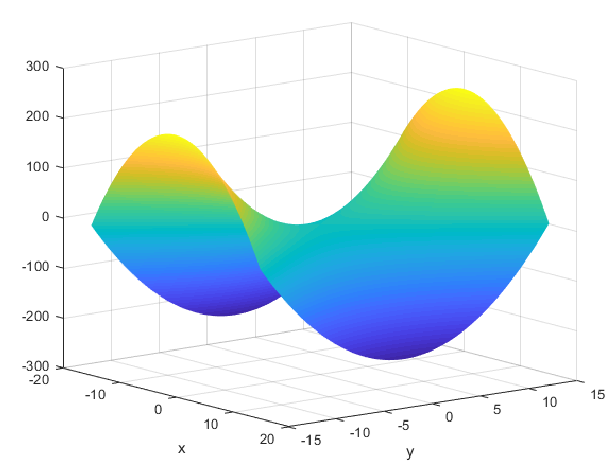

## Introducción

En la anterior sesión se vieron las principales funciones que permiten la representación gráfica en espacios de dos dimensiones. En esta sesión continuaremos con la representación gráfica de funciones en espacios tridimensionales. En este tipo de espacios podemos representar curvas o superficies.  

## Curvas en espacios tridimensionales

Imagine un objeto que se mueve en un espacio tridimensional y describe una trayectoria a lo largo del tiempo. En este ejemplo, existe una única variable independiente, el tiempo, y la posición del objeto en el espacio se podría describir como tres funciones, $x=f\left(t\right),y=f\left(t\right),\;z=f\left(t\right)$, que dependen únicamente de tiempo transcurrido.

En estos casos, el procedimiento para representar la posición en función del tiempo sería análogo al caso de espacios bidimensionales, esto es:

- Creamos el vector con los valores de la variable independiente

- Evaluamos las funciones para cada uno de los valores de la variable independiente

- Representamos la función. 

Para representar las curvas en un espacio tridimensional utilizaremos la función *plot3*.

### plot3

Esta función es similar a la que vimos en el caso de espacios de dos dimensiones, pero tiene como parámetros de entrada un mínimo de tres vectores o matrices. Los elementos de estos vectores o matrices forman tripletes $\left(X_i ,Y_i ,Z_i \right)$ que forman parte de la curva que se quiere representar. Vea el siguiente ejemplo:

t = 0:0.01:20;
xt = t.*sin(2*pi*t);
yt = t.*cos(2*pi*t);
zt = 0.2*t;
f=figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


c=plot3(xt,yt,zt)

c =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×2001 double]
              YData: [1×2001 double]
              ZData: [1×2001 double]

  Show all properties


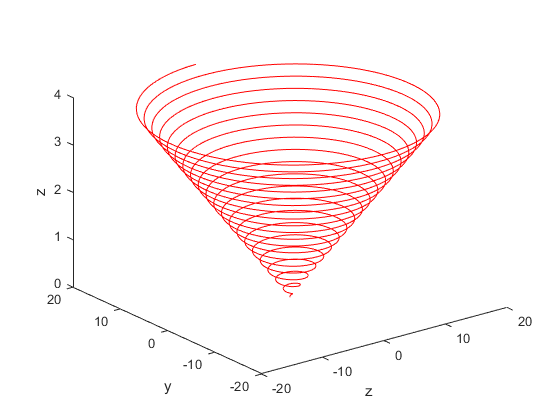

c.Color='red';
xlabel('z'), ylabel('y'), zlabel('z')

Si selecciona la figura puede rotar la vista de la misma. Una vez seleccionada la rotación, con el botón derecho puede encontrar algunas opciones de visualización.

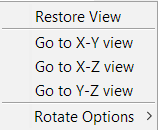

#### Ejercicio 1

Represente la curva definida por las siguientes ecuaciones:


$$\begin{array}{l}
x\left(t\right)=\cos \left(m*t\right)*\cos \left(c\right)\\
y\left(t\right)=\sin \left(m*t\right)*\cos \left(c\right)\\
z\left(t\right)=-\sin \left(c\right)
\end{array}$$


donde $m=50\pi$, $c=\tan^{-1} \left(a\cdot t\right)$ y $a=20$, para $t$ entre -10 y 10.

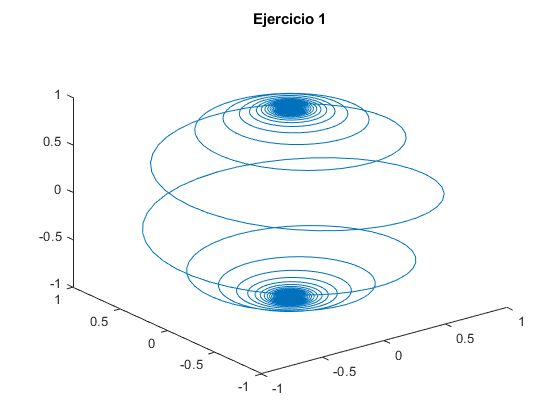

figure("Name","Ejercicio 1");
m = 50*pi;a = 20; 
t = -10:0.001:10;
c = atan(a*t);
x = cos(m*t).*cos(c);
y = sin(m*t).*cos(c);
z = -sin(c);

plot3(x,y,z);title("Ejercicio 1");

#### Ejercicio 2

La curva Viviani es la intersección entre una esfera y un cilindro que pasa por el centro de la esfera y tiene radio igual a la mitad del radio de la esfera. Esta curva está definida por las siguientes ecuaciones:


$$\begin{array}{l}
x\left(t\right)=R\cdot \cos^2 \left(t\right)\\
y\left(t\right)=R\cdot \cos \left(t\right)\cdot \sin \left(t\right)\\
z\left(t\right)=R\cdot \sin \left(t\right)
\end{array}$$


siendo $R$ el radio de la esfera. Represente la curva de Viviani con $R=3$ y $t$ entre 0 y $2\pi$

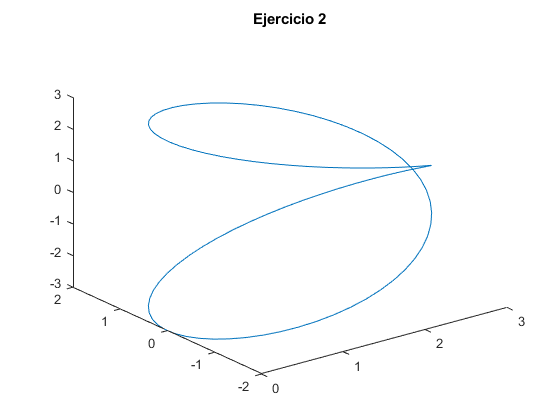


figure("Name","Ejercicio 2");R = 3;
t = linspace(0,2*pi);
x = R*(cos(t).^2);
y =R.*cos(t).*sin(t);
z = R*sin(t);

plot3(x,y,z);title("Ejercicio 2");

#### Ejercicio 3

Cargue los datos de fichero de ejemplo seamount.mat. Este fichero incluye diferentes posiciones de una montaña submarina donde 'x', 'y' y 'z' representan respectivamente la longitud, la latitud ( ambas en grados) y la profundidad (en pies). 

Utilice plot3 para representar los datos. A través de las opciones de representación, modifique la figura para representar cada punto con una marcador cuadrado de color rojo y tamaño 16. Etiquete los ejes.

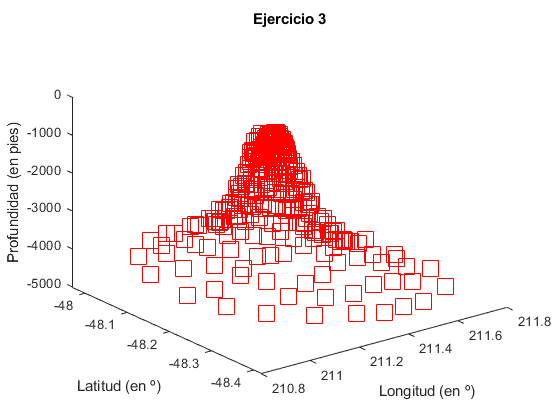

clc;clear
load('seamount.mat');
plot3(x,y,z,"rs","MarkerSize",16);title("Ejercicio 3");
xlabel("Longitud (en º)");ylabel("Latitud (en º)");zlabel("Profundidad (en pies)")

## Superficies en espacios tridimensionales

Hasta ahora hemos visto como representar curvas y datos en espacios tridimensionales. A continuación veremos cómo representar superficies en el espacio. 

### surf, mesh

Una superficie es una función de dos variables independientes que puede expresarse de la forma $z=f\left(x,y\right)$. Veamos el ejemplo de un plano. La ecuación general de un plano es $A\cdot x+B\cdot y+C\cdot z+D=0$, siendo $A,B,C\;y\;D$ constantes. Si despejamos $z$ de la ecuación general obtenemos que $z=-\frac{A}{C}\cdot x-\frac{B}{C}\cdot y-\frac{D}{C}$.

En general, para representar este tipo de superficies, utilizaremos las funciones *surf* o *mesh* junto con la función *meshgrid,* que ya utilizamos en la sesión anterior junto con las funciones *pcolor* y *contour*. Recordemos que la función *meshgrid* crea una malla de puntos  donde se evalúa la función.

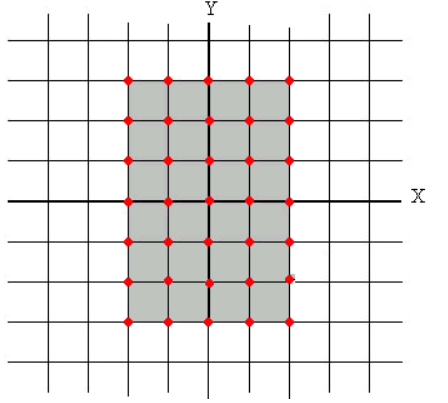

Veamos un ejemplo de como representar el plano $9x-3y+z-2=0$.

x=-10:0.1:10;
y=-10:0.1:10;
[X,Y]=meshgrid(x,y);
Z=-9*X+3*Y+2;
figure
s=surf(X,Y,Z)

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [201×201 double]
           YData: [201×201 double]
           ZData: [201×201 double]
           CData: [201×201 double]

  Show all properties


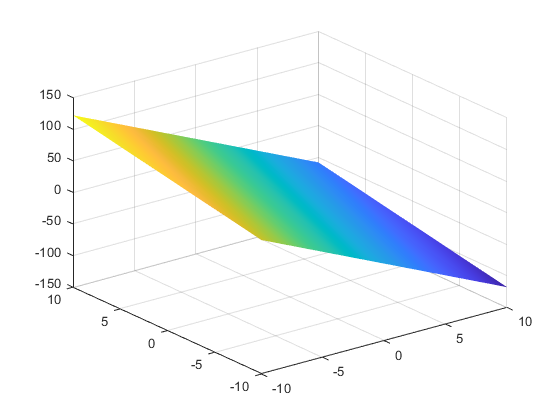

shading interp

Dibujemos ahora una recta perpendicular al plano anterio que pase por el punto (1,3,2), que pertenece al plano. Sabemos que el vector $\overrightarrow{v} =\left(9,-3,1\right)$ es perpendicular al plano y por tanto la ecuación de la recta perpendicular a este plano vendrá definida por$\left(x,y,z\right)=\left(1,3,2\right)+\alpha \cdot \left(9,-3,1\right)$

hold on
a=-12:0.1:12;
rx=1+9*a;
ry=3-3*a;
rz=2+a;
lin=plot3(rx,ry,rz)

lin =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×241 double]
              YData: [1×241 double]
              ZData: [1×241 double]

  Show all properties


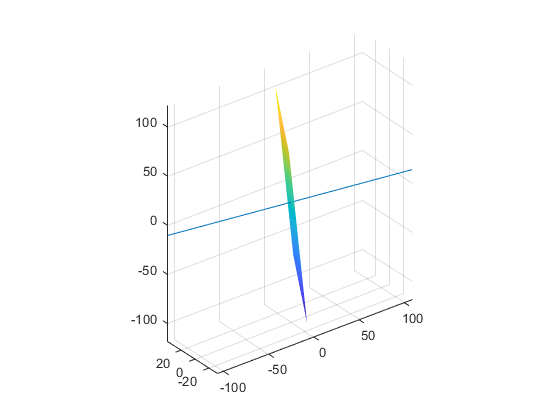

axis equal
hold off

La instrucción axis equal mantiene las proporciones entre los ejes. Pruebe a representar de nuevo el plano y la recta sin esta instrucción. Observe que las distintas escalas puede alterar la percepción de la perpendicularidad de la recta respecto al plano.

#### Ejercicio 4

Utilizaremos de nuevo los datos cargados del fichero seamount.mat (Variables 'x', 'y' y 'z'). Genere una malla de puntos que contenga al menos 50 puntos en 'x' entre el mínimo y el máximo valor de la variable 'x' y 50 puntos en 'y' entre el valor minimo  y el máximo valor de la variable 'y'. 

Gracias a la función *griddata* realizamos una interpolación 3d de los puntos de z sobre la malla de puntos creada. Representa la superficie creada.

clear;clc;
load('seamount.mat');


eje_x = linspace(min(x),max(x),60)

eje_x =   210.8900  210.9031  210.9161  210.9292  210.9422  210.9553  210.9683  210.9814  210.9944  211.0075  211.0205  211.0336  211.0466  211.0597  211.0727  211.0858  211.0988  211.1119  211.1249  211.1380  211.1510  211.1641  211.1771  211.1902  211.2032  211.2163  211.2293  211.2424  211.2554  211.2685  211.2815  211.2946  211.3076  211.3207  211.3337  211.3468  211.3598  211.3729  211.3859  211.3990  211.4120  211.4251  211.4381  211.4512  211.4642  211.4773  211.4903  211.5034  211.5164  211.5295


eje_y = linspace(min(y),max(y),60)

eje_y =   -48.4200  -48.4124  -48.4047  -48.3971  -48.3895  -48.3819  -48.3742  -48.3666  -48.3590  -48.3514  -48.3437  -48.3361  -48.3285  -48.3208  -48.3132  -48.3056  -48.2980  -48.2903  -48.2827  -48.2751  -48.2675  -48.2598  -48.2522  -48.2446  -48.2369  -48.2293  -48.2217  -48.2141  -48.2064  -48.1988  -48.1912  -48.1836  -48.1759  -48.1683  -48.1607  -48.1531  -48.1454  -48.1378  -48.1302  -48.1225  -48.1149  -48.1073  -48.0997  -48.0920  -48.0844  -48.0768  -48.0692  -48.0615  -48.0539  -48.0463



[xq,yq] = meshgrid(eje_x, eje_y)

xq =   210.8900  210.9031  210.9161  210.9292  210.9422  210.9553  210.9683  210.9814  210.9944  211.0075  211.0205  211.0336  211.0466  211.0597  211.0727  211.0858  211.0988  211.1119  211.1249  211.1380  211.1510  211.1641  211.1771  211.1902  211.2032  211.2163  211.2293  211.2424  211.2554  211.2685  211.2815  211.2946  211.3076  211.3207  211.3337  211.3468  211.3598  211.3729  211.3859  211.3990  211.4120  211.4251  211.4381  211.4512  211.4642  211.4773  211.4903  211.5034  211.5164  211.5295
  210.8900  210.9031  210.9161  210.9292  210.9422  210.9553  210.9683  210.9814  210.9944  211.0075  211.0205  211.0336  211.0466  211.0597  211.0727  211.0858  211.0988  211.1119  211.1249  211.1380  211.1510  211.1641  211.1771  211.1902  211.2032  211.2163  211.2293  211.2424  211.2554  211.2685  211.2815  211.2946  211.3076  211.3207  211.3337  211.3468  211.3598  211.3729  211.3859  211.3990  211.4120  211.4251  211.4381  211.4512  211.4642  211.4773  211.4903  211.5034  211.5164  21

yq =   -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200  -48.4200
  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -48.4124  -4


malla = griddata(x, y, z, xq, yq)

malla = 	1.0e+03 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   -4.2500   -4.2500   -4.2500   -4.2500   -4.2500   -4.2500   -4.2500   -4.2500   -4.2500   -4.2500   -4.2500   -4.2500       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   -4.2274   -4.2034   -4.1890   -4.1890   -4.1890   -4.1890   -4.1890   -4.1890   -4.1965   -4.1966   -4.1966   -4.1966   -4.1966   -4.1966   -4.2160   -4.2311   -4.2446       Na

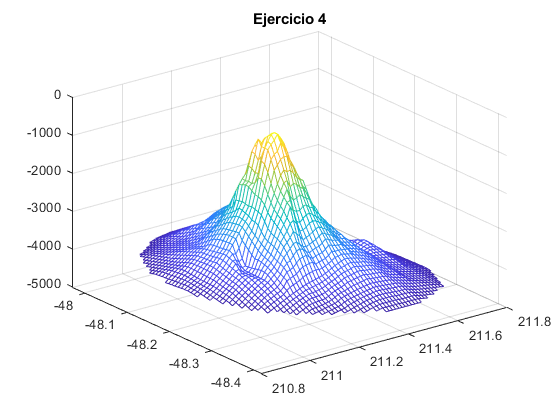


mesh(xq,yq,malla);title("Ejercicio 4");

## Superficies de revolución

Las superficies de revolución se generan al rotar una curva plana sobre una recta, llamada eje de revolución. Estas superficies son importantes en ingeniería y diseño.

### cylinder

La función cylinder de MATLAB nos permite simplificar el proceso de representar una superficie de revolución.

help cylinder

cylinder - Create cylinder

    This MATLAB function returns the x-, y-, and z- coordinates of a cylinder
    without drawing it.

    [X,Y,Z] = cylinder
    [X,Y,Z] = cylinder(r)
    [X,Y,Z] = cylinder(r,n)
    cylinder(___)
    cylinder(ax,___)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/ellipsoid.html">ellipsoid</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/mesh.html">mesh</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/sphere.html">sphere</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/surf.html">surf</a>

    Documentation for cylinder



#### Ejercicio 5

Represente la surperficie de revolución dada por la curva $y=-\frac{1}{x}$ y el eje $\overrightarrow{z}$ como eje de revolución con $x\in \left\lbrack 2,5\right\rbrack$.

clc;clear;
x = 2:0.01:5;
y = -(1./x);

[X,Y,Z] = cylinder(y)

X =    -0.5000   -0.4755   -0.4045   -0.2939   -0.1545   -0.0000    0.1545    0.2939    0.4045    0.4755    0.5000    0.4755    0.4045    0.2939    0.1545    0.0000   -0.1545   -0.2939   -0.4045   -0.4755   -0.5000
   -0.4975   -0.4732   -0.4025   -0.2924   -0.1537   -0.0000    0.1537    0.2924    0.4025    0.4732    0.4975    0.4732    0.4025    0.2924    0.1537    0.0000   -0.1537   -0.2924   -0.4025   -0.4732   -0.4975
   -0.4950   -0.4708   -0.4005   -0.2910   -0.1530   -0.0000    0.1530    0.2910    0.4005    0.4708    0.4950    0.4708    0.4005    0.2910    0.1530    0.0000   -0.1530   -0.2910   -0.4005   -0.4708   -0.4950
   -0.4926   -0.4685   -0.3985   -0.2895   -0.1522   -0.0000    0.1522    0.2895    0.3985    0.4685    0.4926    0.4685    0.3985    0.2895    0.1522    0.0000   -0.1522   -0.2895   -0.3985   -0.4685   -0.4926
   -0.4902   -0.4662   -0.3966   -0.2881   -0.1515   -0.0000    0.1515    0.2881    0.3966    0.4662    0.4902    0.4662    0.3966    0.2881    0.1515  

Y =          0   -0.1545   -0.2939   -0.4045   -0.4755   -0.5000   -0.4755   -0.4045   -0.2939   -0.1545   -0.0000    0.1545    0.2939    0.4045    0.4755    0.5000    0.4755    0.4045    0.2939    0.1545         0
         0   -0.1537   -0.2924   -0.4025   -0.4732   -0.4975   -0.4732   -0.4025   -0.2924   -0.1537   -0.0000    0.1537    0.2924    0.4025    0.4732    0.4975    0.4732    0.4025    0.2924    0.1537         0
         0   -0.1530   -0.2910   -0.4005   -0.4708   -0.4950   -0.4708   -0.4005   -0.2910   -0.1530   -0.0000    0.1530    0.2910    0.4005    0.4708    0.4950    0.4708    0.4005    0.2910    0.1530         0
         0   -0.1522   -0.2895   -0.3985   -0.4685   -0.4926   -0.4685   -0.3985   -0.2895   -0.1522   -0.0000    0.1522    0.2895    0.3985    0.4685    0.4926    0.4685    0.3985    0.2895    0.1522         0
         0   -0.1515   -0.2881   -0.3966   -0.4662   -0.4902   -0.4662   -0.3966   -0.2881   -0.1515   -0.0000    0.1515    0.2881    0.3966    0.4662  

Z =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033
    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067
    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100
    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133  

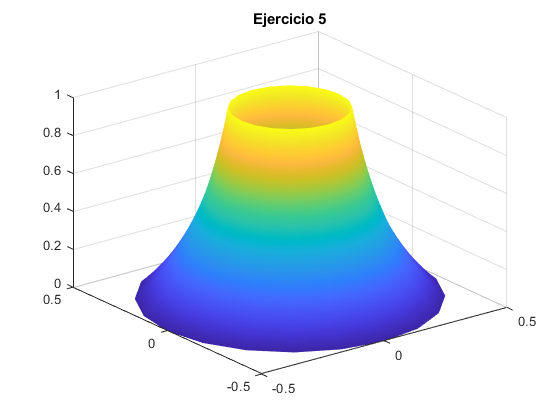


mesh(X,Y,Z);title("Ejercicio 5");

## Otras representaciones en espacios tridimensionales

### scatter3

Es una extensión de la función *scatter *de dos dimensiones. A diferencia de *plot3* permite controlar el tamaño y color de los puntos representados.

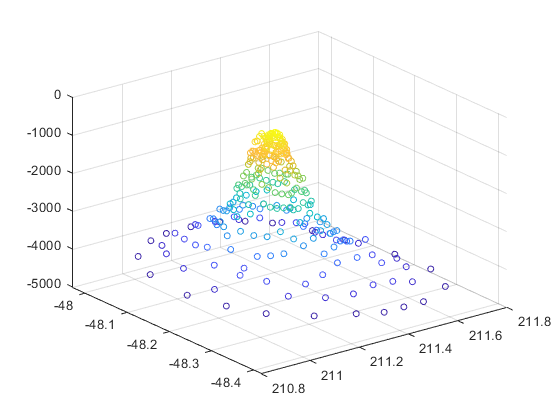

load seamount.mat
figure, scatter3(x,y,z,20,z)

### bar3

Esta función también es una extensión de la función bar y permite representar gráficos de barras tridimensionales.

load Pob.mat                                % Datos estadísticos de Población C. Madrid
b=bar3(Pob.Ano,table2array(Pob(:,15:-1:10)))

b =   1×6 Surface array:

    Surface    Surface    Surface    Surface    Surface    Surface


zlabel('% Población')
ylabel('Año')
ax=gca

ax =   Axes with properties:

             XLim: [0.6000 6.4000]
             YLim: [1960 2020]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


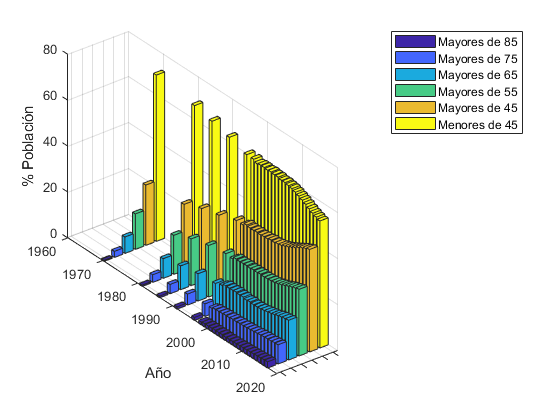

ax.XTickLabel=[];
legend({'Mayores de 85', 'Mayores de 75', 'Mayores de 65', 'Mayores de 55', ...
    'Mayores de 45', 'Menores de 45'})

## Ejercicios adicionales

**MATLAB for Data Processing and Visualization**

**Images and 3-D Surface Plots**

[https://matlabacademy.mathworks.com/R2020a/portal.html?course=mlvi](https://matlabacademy.mathworks.com/R2020a/portal.html?course=mlvi)